Reading in data

imread("data32\test\animal animal_faces cat cat_face\0BGPHALKEI6K.jpg", "jpg")

ans = 32×32×3 uint8 array
ans(:,:,1) =

   164   171   166   159   159   150   150   145   137   140   117    76    61    72    84    86    90    90    90    88    89    87    87    89    88    90    88    87    84    76    77    72
   170   172   169   158   159   155   150   143   140   141   116    75    59    71    83    86    87    88    89    88    90    92    92    88    90    93    92    86    84    82    79    71
   152   173   172   164   157   150   148   141   137   139   114    76    62    71    80    82    81    80    86    92    92    88    90    93    90    88    82    83    80    83    69    71
   150   172   165   160   156   151   146   142   136   140   116    76    62    72    79    82    80    80    85    89    90    95    95    87    85    88    81    80    76    72    72    70
   149   169   167   158   156   147   139   138   135   140   118    76    60    71    81    83    79    82    85    89    91    92    90    86    81    76    87   137   136    74    65  


imagefiles = dir("data32\test\animal animal_faces cat cat_face\*.jpg")

imagefiles = 1661×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


filepath = "data32\test\animal animal_faces cat cat_face"

filepath = "data32\test\animal animal_faces cat cat_face"

for ii=1:50
   currentfilename = imagefiles(ii).name;
   currentimage = imread(filepath + "\" +  currentfilename);
   images{ii} = currentimage;
end

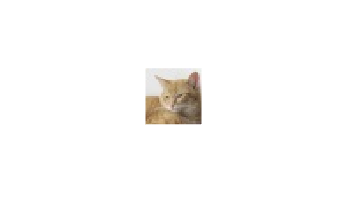

imshow(images{1})

Reproduce image

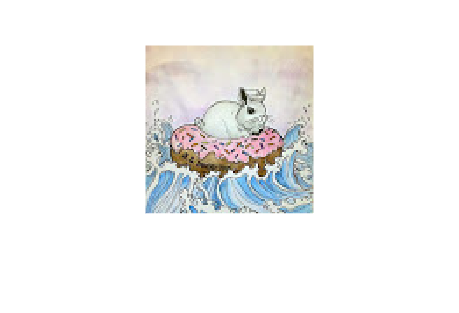

targetImage = imread("imageToRep.jpg");

imshow(targetImage)


[l, h, d] = size(targetImage)

l = 96

h = 96

d = 3

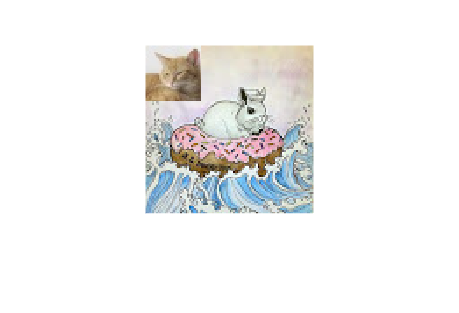


targetImage(1:32, 1:32, :) = images{1};

imshow(targetImage)